# Gain Scheduling

#### Basic gain scheduling

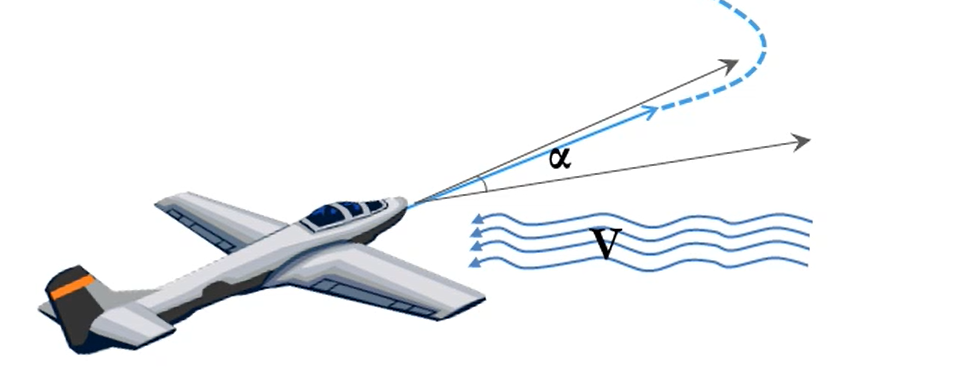

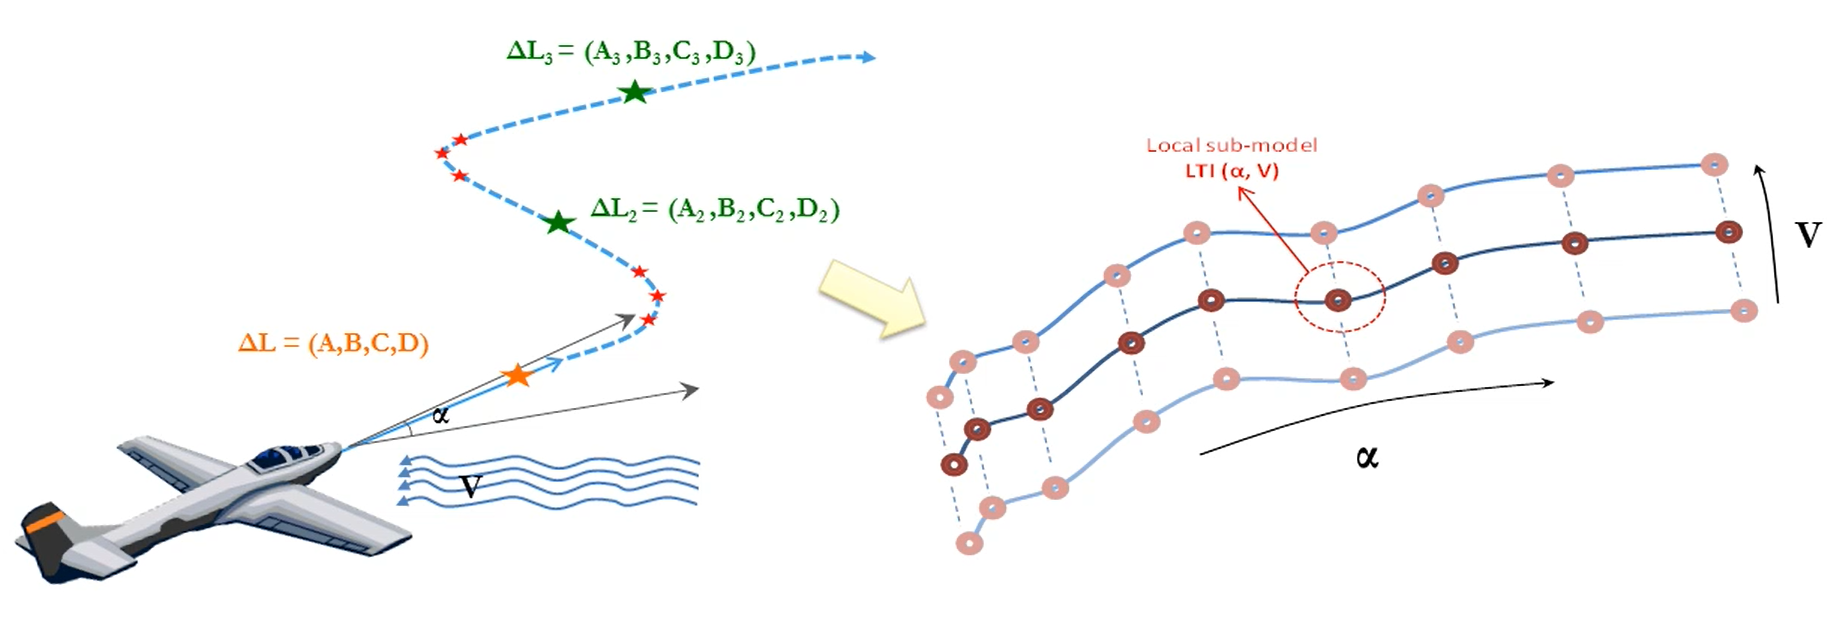

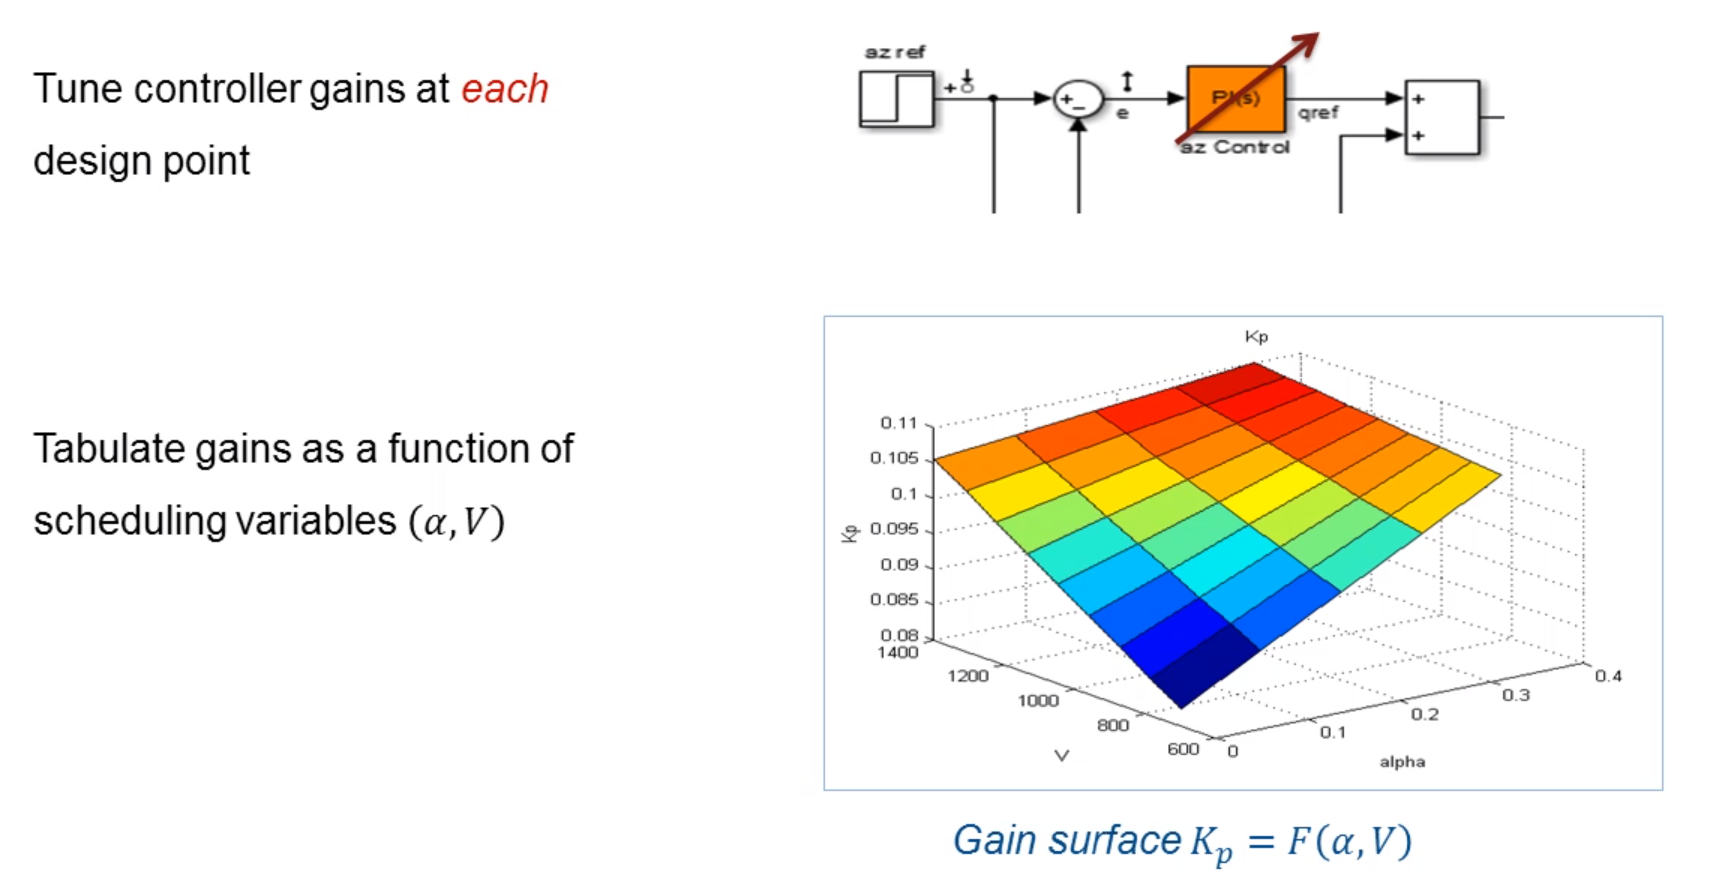

#### Auto gain scheduling

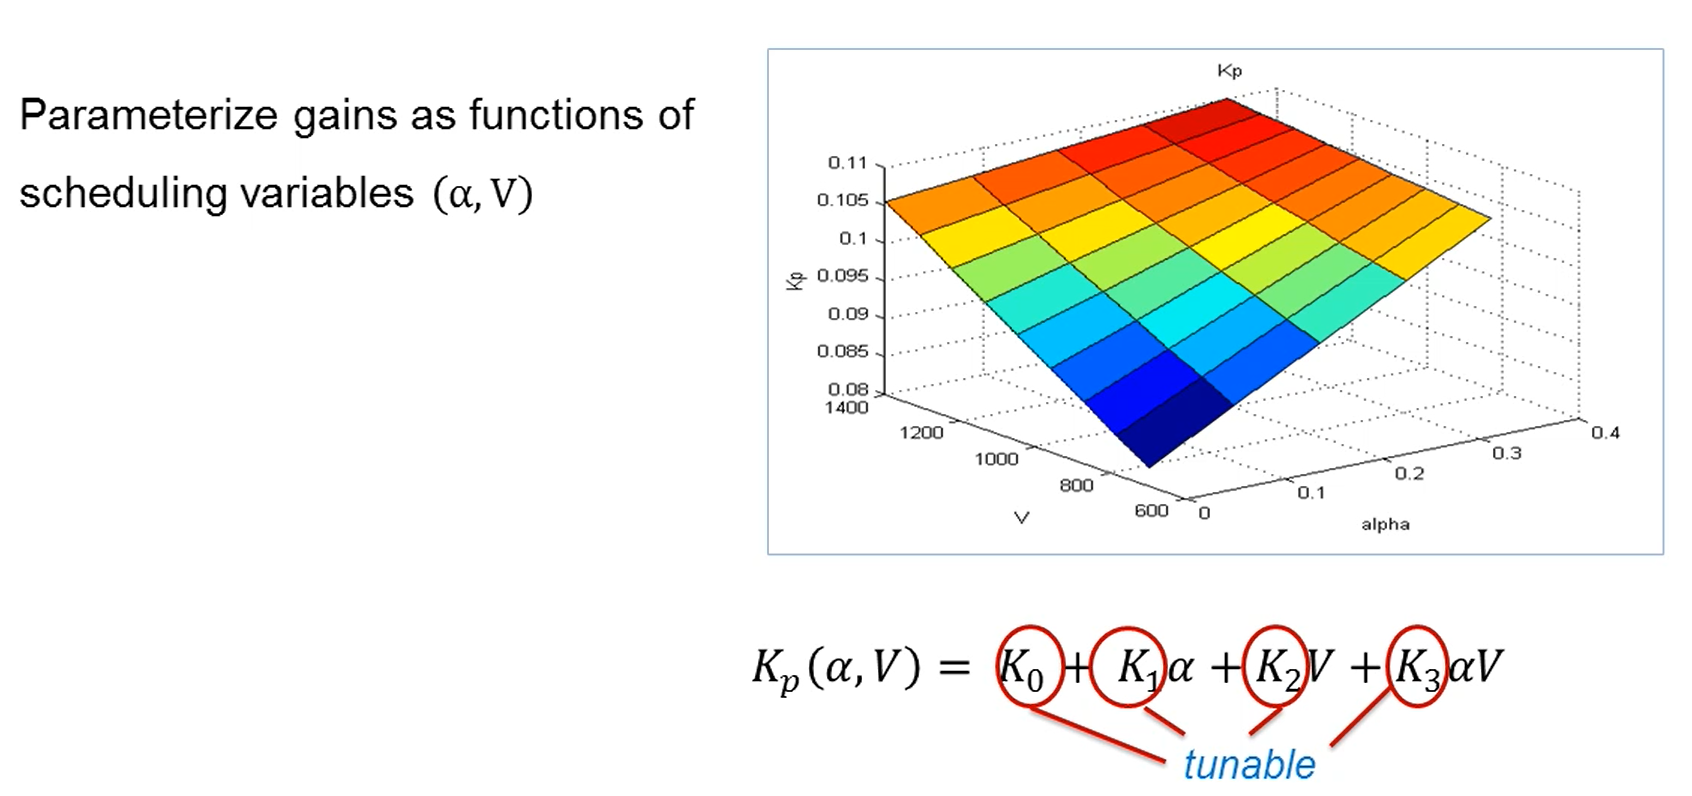

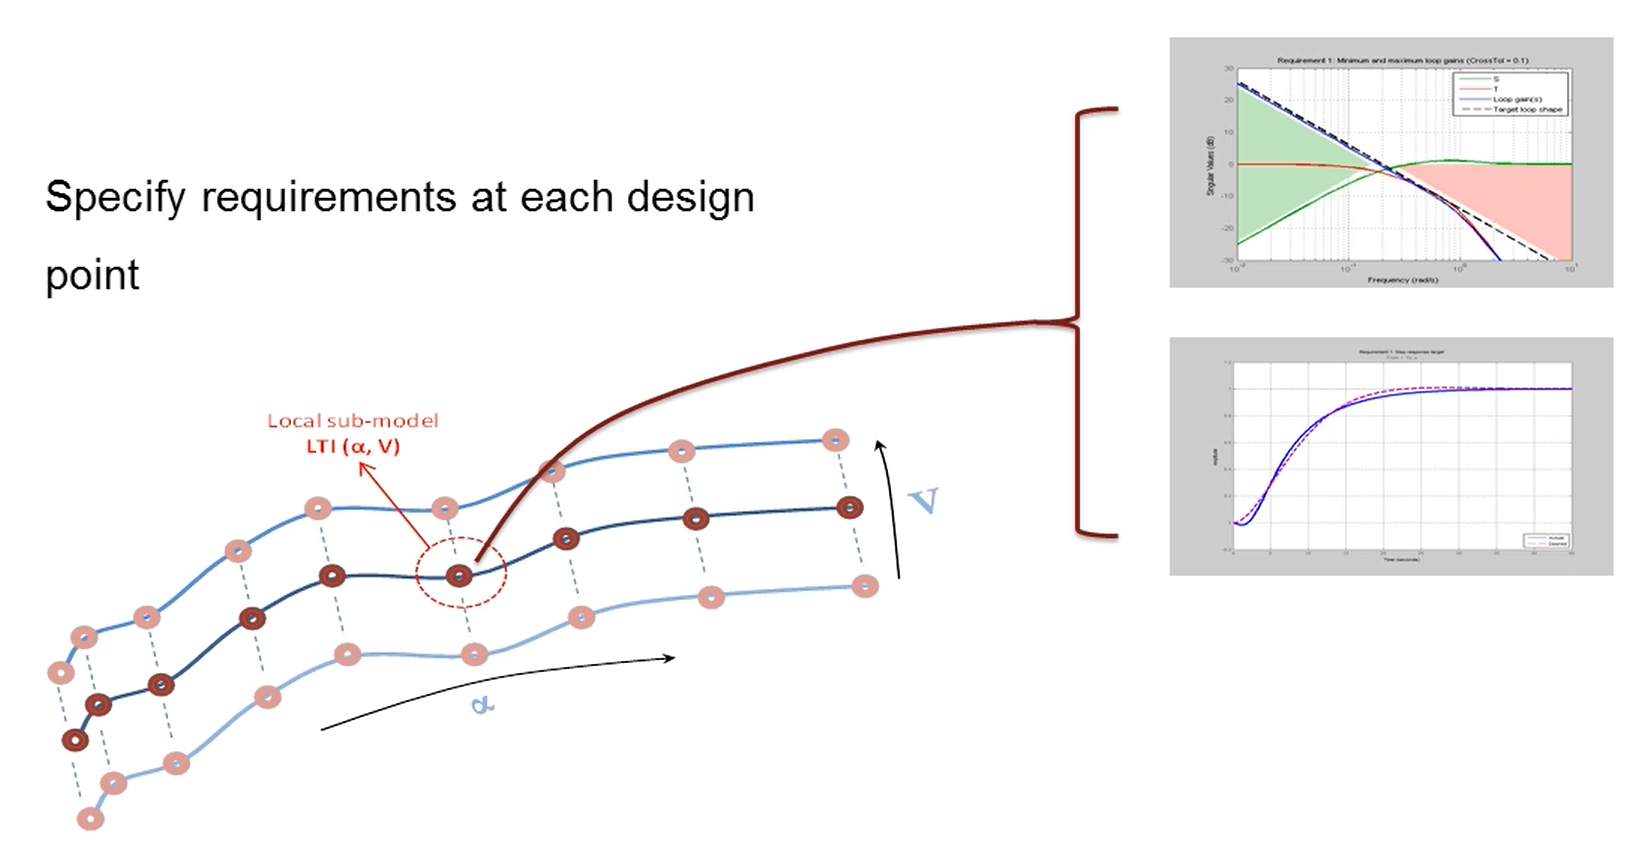

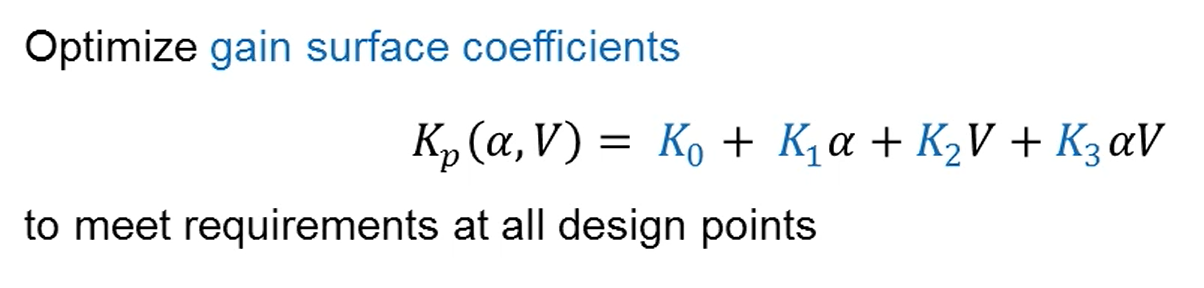

#### Пример

В качестве примера применим данный метод к системе трехконтурного управления углом тангажа.

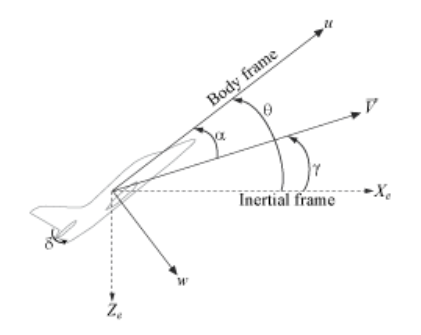

В модели используется трехконтурная структура автопилота для управления углом траектории полета gamma. Этот автопилот корректирует траекторию полета, обеспечивая достаточные всплески нормального ускорения a_z (ускорение вдоль omega). В свою очередь, нормальное ускорение создается путем регулировки отклонения руля высоты delta, чтобы вызвать тангаж и изменить величину подъемной силы. Автопилот использует пропорционально-интегральное (ПИ) управление в контуре угловой скорости тангажа q=theta_dot и пропорциональное управление в контурах a_z и gamma. Замкнутая система смоделирована в Simulink.

open_system('rct_airframeGS')

Настроечные параметры: скорость V и угол атаки alpha, так как аэродинамические силы и моменты зависят от эти параметров.

Соответственно коэффициенты регуляторов будут зависеть от V и alpha, которые мы будем выбирать используя таблицы поиска и последующюю интерполяцию по найденной поверхности.

### Линеаризация

nA = 5;  % number of alpha values
nV = 9;  % number of V values
[alpha,V] = ndgrid(linspace(0,20,nA)*pi/180,linspace(700,1400,nV));

Для каждой рабочей точки (V, alpha) линеаризуем систему в положении (нулевое нормальное ускорение и нулевой тангажный момент) для этого необходимо вычислить delta и q

mdl = 'rct_airframeTRIM';
open_system(mdl)

Используем operspec для задания положения, findop для вычисления значений delta и q, и линеаризуем динамику планера для полученных рабочих точек.

for ct=1:nA*nV
   alpha_ini = alpha(ct);      % Incidence [rad]
   v_ini = V(ct);              % Speed [m/s]

   % Specify trim condition
   opspec(ct) = operspec(mdl);
   % Xe,Ze: known, not steady
   opspec(ct).States(1).Known = [1;1];
   opspec(ct).States(1).SteadyState = [0;0];
   % u,w: known, w steady
   opspec(ct).States(3).Known = [1 1];
   opspec(ct).States(3).SteadyState = [0 1];
   % theta: known, not steady
   opspec(ct).States(2).Known = 1;
   opspec(ct).States(2).SteadyState = 0;
   % q: unknown, steady
   opspec(ct).States(4).Known = 0;
   opspec(ct).States(4).SteadyState = 1;
end
opspec = reshape(opspec,[nA nV]);

Подставим найденные значения 

Options = findopOptions('DisplayReport','off');
op = findop(mdl,opspec,Options);

Линеаризуем модель

G = linearize(mdl,op);
G.u = 'delta';
G.y = {'alpha','V','q','az','gamma','h'};
G.SamplingGrid = struct('alpha',alpha,'V',V);

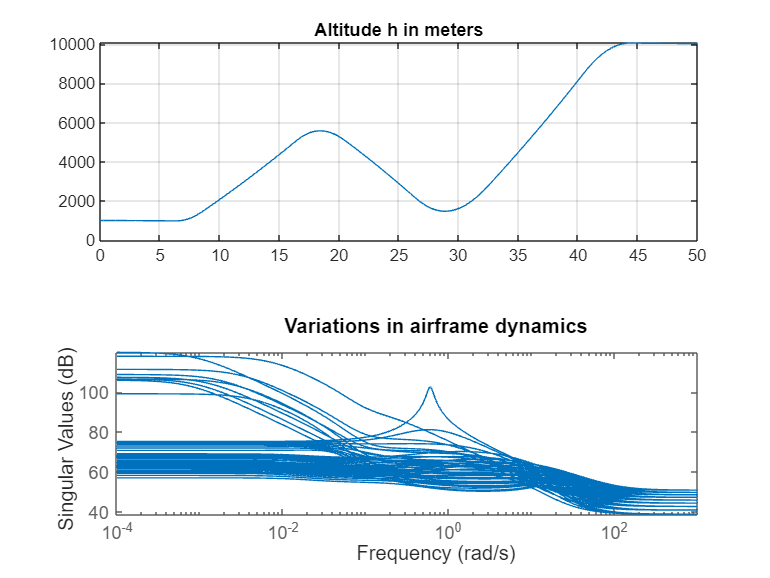

sigma(G)
title('Variations in airframe dynamics')

Динамика существенно меняется в различных рабочих точках.

#### Tunable gain surface

Управление состоит из четырех коэффициентов усиления Kp, Ki, Ka, Kg, которые необходимо регулировать в зависимости от V и alpha. Практически это означает настройку 88 значений в каждой из соответствующих четырех таблиц. Вместо того чтобы настраивать каждый элемент таблицы отдельно, параметризуем усиления в виде двумерных поверхностей усиления, например, поверхностей с простой мультилинейной зависимостью K(alpha,V) = K0 + K1*alpha + K2*V + K3*V*alpha:

Это сокращает количество переменных с 88 до 4 для каждой таблицы поиска. 

Будем использовать tunableSurface для параметризации каждой поверхности усиления.

TuningGrid = struct('alpha',alpha,'V',V);
ShapeFcn = @(alpha,V) [alpha,V,alpha*V];

Kp = tunableSurface('Kp',0.1, TuningGrid,ShapeFcn);
Ki = tunableSurface('Ki',2, TuningGrid,ShapeFcn);
Ka = tunableSurface('Ka',0.001, TuningGrid,ShapeFcn);
Kg = tunableSurface('Kg',-1000, TuningGrid,ShapeFcn);

Создадим интерфейс slTuner для настройки поверхностей усиления. Используем подстановку блоков для замены нелинейной модели установки на линеаризованные модели по сетке настройки. 

setBlockParam связывает настраиваемые поверхности усиления Kp, Ki, Ka, Kg с одноименными блоками интерполяции.

BlockSubs = struct('Name','rct_airframeGS/Airframe Model','Value',G);
ST0 = slTuner('rct_airframeGS',{'Kp','Ki','Ka','Kg'},BlockSubs);

% Register points of interest
ST0.addPoint({'az_ref','az','gamma_ref','gamma','delta'})

% Parameterize look-up table blocks
ST0.setBlockParam('Kp',Kp,'Ki',Ki,'Ka',Ka,'Kg',Kg);

#### Установка ограничений

systune может автоматически настраивать коэффициенты поверхности усиления для всей огибающей полета. 

используем объекты TuningGoal, чтобы указать цели управления:

-  контур угла траектории полета gamma: Отслеживает заданное значение с временем отклика 1 с, погрешность в установившемся режиме составляет менее 2%, а пиковая погрешность - менее 30%.

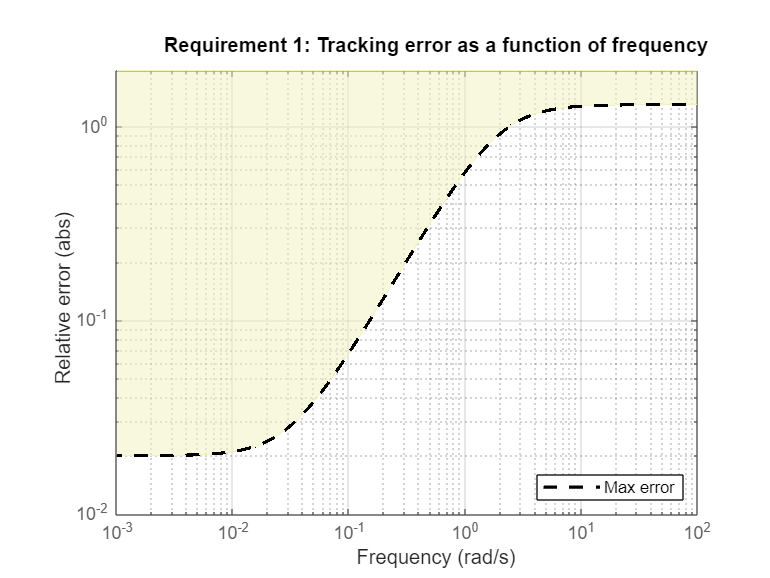

Req1 = TuningGoal.Tracking('gamma_ref','gamma',1,0.02,1.3);
viewGoal(Req1)

2. контур нормального ускорения a_z: Обеспечим хорошее подавление помех на низкой частоте (для отслеживания требований к ускорению) и при скорости более 10 рад/с (для нечувствительности к шуму измерений). Возмущение подается в точку az_ref.

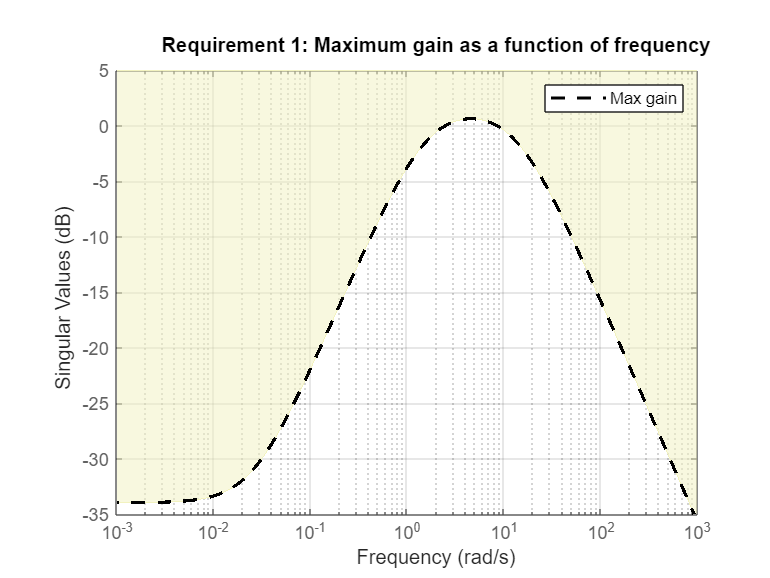

RejectionProfile = frd([0.02 0.02 1.2 1.2 0.1],[0 0.02 2 15 150]);
Req2 = TuningGoal.Gain('az_ref','az',RejectionProfile);
viewGoal(Req2)

3. контур угловой скорости тангажа q: Обеспечим хорошее подавление помех до 10 рад/с. Возмущение подается на дельту входного сигнала установки.

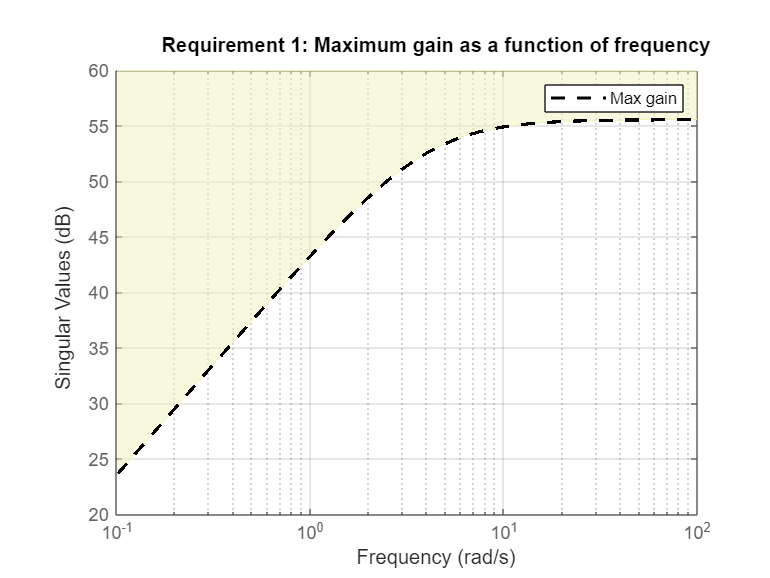

Req3 = TuningGoal.Gain('delta','az',600*tf([0.25 0],[0.25 1]));
viewGoal(Req3)

4. Переходные процессы: Обеспечим минимальный коэффициент демпфирования 0,35 для отсутствия колебаний в переходных процессах

MinDamping = 0.35;
Req4 = TuningGoal.Poles(0,MinDamping);

С помощью systune настроим 16 коэффициентов поверхности усиления, чтобы они наилучшим образом соответствовали этим требованиям при всех 45 условиях полета.

ST = systune(ST0,[Req1 Req2 Req3 Req4]);

Final: Soft = 1.13, Hard = -Inf, Iterations = 57


Итоговое значение комбинированной цели близко к 1, что говорит о том, что все требования почти выполнены. Визуализируем результирующие поверхности усиления.

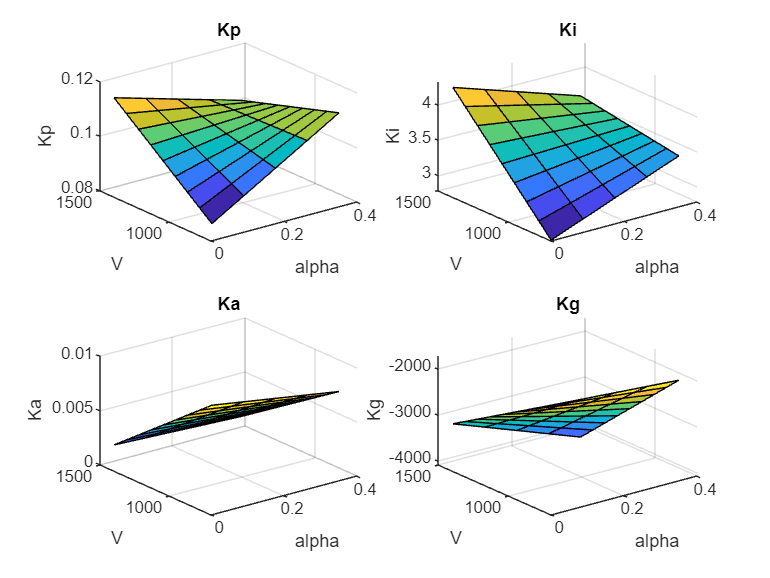

% Get tuned gain surfaces.
TGS = getBlockParam(ST);

% Plot gain surfaces.
clf
subplot(2,2,1)
viewSurf(TGS.Kp)
title('Kp')
subplot(2,2,2)
viewSurf(TGS.Ki)
title('Ki')
subplot(2,2,3)
viewSurf(TGS.Ka)
title('Ka')
subplot(2,2,4)
viewSurf(TGS.Kg)
title('Kg')

#### Валидация

Проверим работу настроенного автопилота при 45 рассмотренных выше условиях полета. Построим график реакции на ступенчатое изменение угла траектории полета и реакцию на ступенчатое изменение отклонения руля высоты.

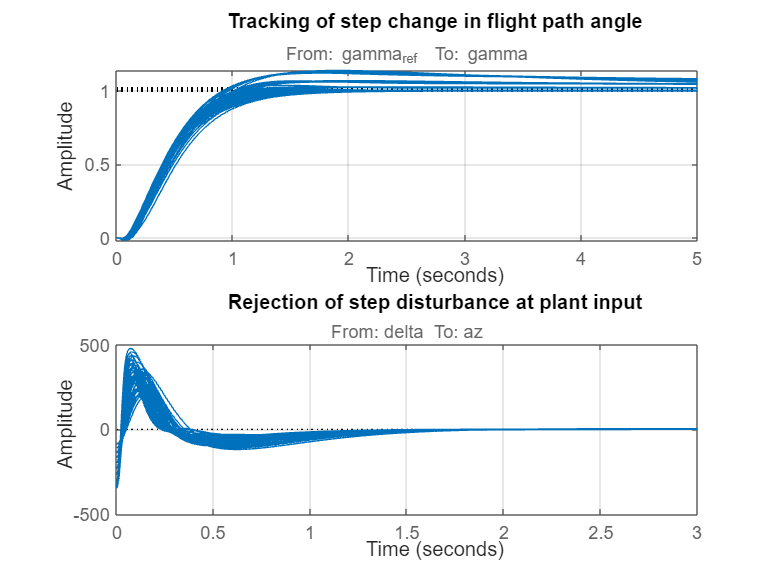

clf
subplot(2,1,1)
step(getIOTransfer(ST,'gamma_ref','gamma'),5)
grid
title('Tracking of step change in flight path angle')
subplot(2,1,2)
step(getIOTransfer(ST,'delta','az'),3)
grid
title('Rejection of step disturbance at plant input')

Процессы удовлетворительны при любых условиях полета. 

Теперь проверим автопилот на нелинейной модели. Сначала используем writeBlockValue, чтобы применить результаты настройки к модели Simulink. При этом оценивается каждая формула поверхности усиления в точках останова, указанных в двух блоках Prelookup, и результат записывается в соответствующий блок Interpolation.

writeBlockValue(ST)

Смоделируем работу автопилота при выполнении маневра, при котором самолет проходит большую часть пространства настроечных параметров (alpha, V).

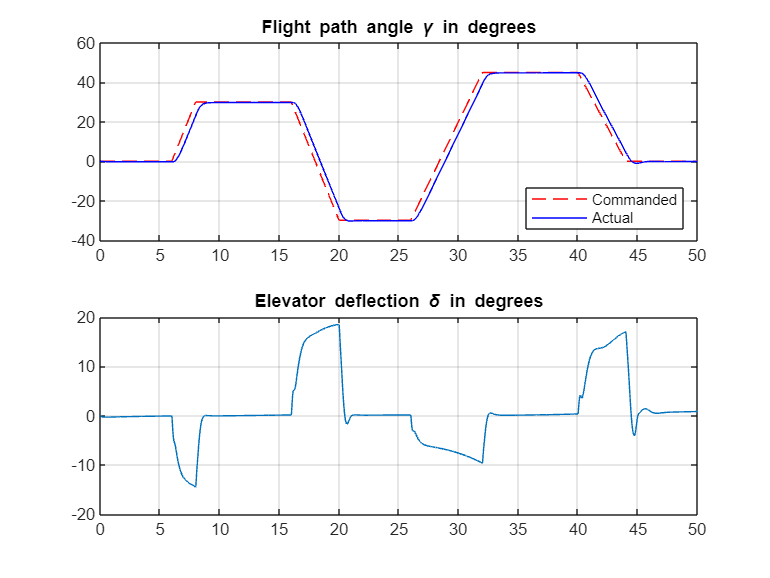

% Specify the initial conditions.
h_ini = 1000;
alpha_ini = 0;
v_ini = 700;

% Simulate the model.
SimOut = sim('rct_airframeGS', 'ReturnWorkspaceOutputs', 'on');

% Extract simulation data.
SimData = get(SimOut,'sigsOut');
Sim_gamma = getElement(SimData,'gamma');
Sim_alpha = getElement(SimData,'alpha');
Sim_V = getElement(SimData,'V');
Sim_delta = getElement(SimData,'delta');
Sim_h = getElement(SimData,'h');
Sim_az = getElement(SimData,'az');
t = Sim_gamma.Values.Time;

% Plot the main flight variables.
clf
subplot(2,1,1)
plot(t,Sim_gamma.Values.Data(:,1),'r--',t,Sim_gamma.Values.Data(:,2),'b')
grid
legend('Commanded','Actual','location','SouthEast')
title('Flight path angle \gamma in degrees')
subplot(2,1,2)
plot(t,Sim_delta.Values.Data)
grid
title('Elevator deflection \delta in degrees')

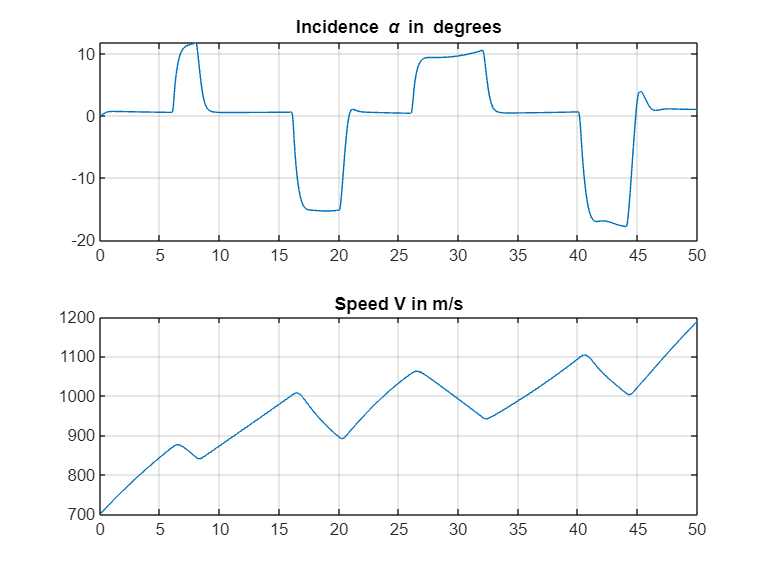

subplot(2,1,1)
plot(t,Sim_alpha.Values.Data)
grid
title('Incidence \alpha in degrees')
subplot(2,1,2)
plot(t,Sim_V.Values.Data)
grid
title('Speed V in m/s')

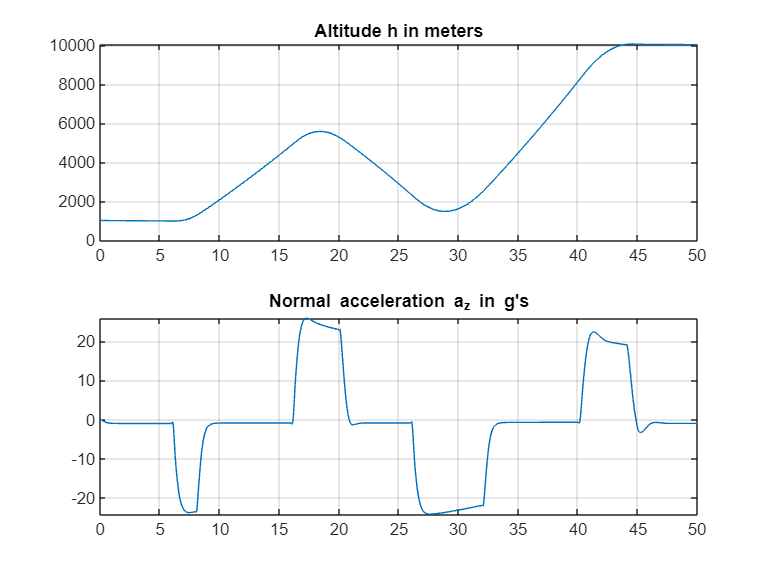

subplot(2,1,1)
plot(t,Sim_h.Values.Data)
grid
title('Altitude h in meters')
subplot(2,1,2)
plot(t,Sim_az.Values.Data)
grid
title('Normal acceleration a_z in g''s')

Отслеживание углового профиля траектории полета остается хорошим на протяжении всего маневра. 

Отметим, что изменения настроечных параметров (угла наклона alpha и скорости V) охватывают большую часть всех возможных значений alpha, V.

Результаты нелинейного моделирования подтверждают, что автопилот, синтезированный по принципу gain scheduling, обеспечивает стабильно высокие характеристики по всему диапазону полета. Процедура "gain surface tuning" предоставляет простые явные формулы для зависимости усиления от переменных планирования. Вместо использования таблиц поиска можно использовать эти формулы напрямую для более экономичной аппаратной реализации.